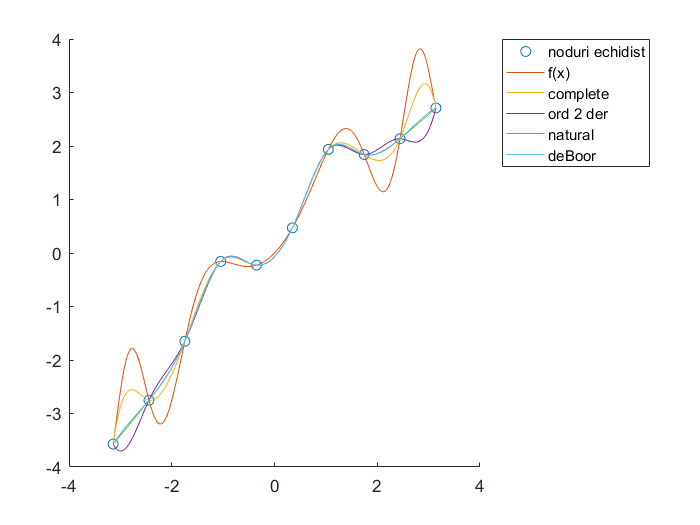

a=-pi;
b=pi;
xx = linspace(a, b, 200);
n = 10;

f = @(x) x + sin(x .^ 2 );
df = @(x) 1 + 2 .* x.* cos(x .^ 2 );
ddf = @(x) 2 .* cos(x .^ 2 ) - 4 .* x .^2 .* sin(x .^ 2);

x = linspace(a, b, 10);
y = f(x);

%%spline complete
[a1, b1, c1, d1] = SplineCub(x, y, 0, [df(a), df(b)]);
yy_complete = valspline(x, a1, b1, c1, d1, xx);

%%spline cu derivate de ordin 2
[a2, b2, c2, d2] = SplineCub(x, y, 1, [ddf(a), ddf(b)]);
yy_ord2 = valspline(x, a2, b2, c2, d2, xx);

%% spline naturale
[a3, b3, c3, d3] = SplineCub(x, y, 2);
yy_natural = valspline(x, a3, b3, c3, d3, xx);

%% spline deBoor
[a4, b4, c4, d4] = SplineCub(x, y, 3);
yy_boor = valspline(x, a4, b4, c4, d4, xx);

figure(1);
hold on;
plot(x, y, 'o');
plot(xx, f(xx));
plot(xx, yy_complete);
plot(xx, yy_ord2);
plot(xx, yy_natural);
plot(xx, yy_boor);

legend('noduri echidist', 'f(x)', 'complete', 'ord 2 der', 'natural', 'deBoor', 'Location', 'BestOutside');

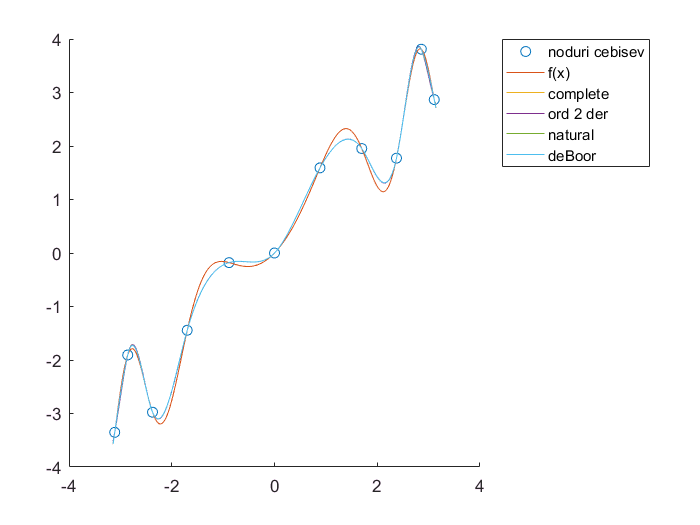


x = sort(1/2*(a+b) + 1/2*(b-a)*cos(((2*[0:n] + 1)*pi/(2*n + 2))));

y = f(x);

%%spline complete
[a1, b1, c1, d1] = SplineCub(x, y, 0, [df(a), df(b)]);
yy_complete = valspline(x, a1, b1, c1, d1, xx);

%%spline cu derivate de ordin 2
[a2, b2, c2, d2] = SplineCub(x, y, 1, [ddf(a), ddf(b)]);
yy_ord2 = valspline(x, a2, b2, c2, d2, xx);

%% spline naturale
[a3, b3, c3, d3] = SplineCub(x, y, 2);
yy_natural = valspline(x, a3, b3, c3, d3, xx);

%% spline deBoor
[a4, b4, c4, d4] = SplineCub(x, y, 3);
yy_boor = valspline(x, a4, b4, c4, d4, xx);

figure(2);
hold on;
plot(x, y, 'o');
plot(xx, f(xx));
plot(xx, yy_complete);
plot(xx, yy_ord2);
plot(xx, yy_natural);
plot(xx, yy_boor);

legend('noduri cebisev', 'f(x)', 'complete', 'ord 2 der', 'natural', 'deBoor', 'Location', 'BestOutside');